# 采用 "# FCD maps: Junction and Extension" 的实现，并复现

## [https://github.com/hkulsgaard/fcd_maps/](https://github.com/hkulsgaard/fcd_maps/)

root_dir = 'D:\File\work_file\Dataset\Brain\openFCD\';

sub_dirs = dir(root_dir); sub_dirs(1:2) = [];
sub_dirs = sub_dirs([sub_dirs.isdir]);
sub_num = length(sub_dirs);

mni_root_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\brainsuit_raw';
mni_frac = MRI_read_Data([mni_root_dir,'\mri.pvc.frac.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


sz = mni_frac.size;
[plX,plY,plZ] = meshgrid(1:sz(2),1:sz(1),1:sz(3));

## transforming cat12+MAP18 fcd_map to mni space

reference_cat12_dir = 'F:\Dataset\Brain\FCD_maps\data\control\references\';
extension_mean_cat12 = MRI_read_Data([reference_cat12_dir,'ref_extension_mean.nii']);

error [bst] mode, try [nifttiread] => 此类型的变量不支持使用点进行索引。
sMRI [137,113,113] res:[1.5,1.5,1.5]


extension_std_cat12 = MRI_read_Data([reference_cat12_dir,'ref_extension_std.nii']);

error [bst] mode, try [nifttiread] => 此类型的变量不支持使用点进行索引。
sMRI [137,113,113] res:[1.5,1.5,1.5]


junction_mean_cat12 = MRI_read_Data([reference_cat12_dir,'ref_junction_mean.nii']);

error [bst] mode, try [nifttiread] => 此类型的变量不支持使用点进行索引。
sMRI [137,113,113] res:[1.5,1.5,1.5]



extension_mean_mni = func_repos_cat12(extension_mean_cat12,mni_frac);

  1    1    1 => 13   13    7
113  137  113 =>182  218  176


extension_std_mni = func_repos_cat12(extension_std_cat12,mni_frac);

  1    1    1 => 13   13    7
113  137  113 =>182  218  176


junction_mean_mni = func_repos_cat12(junction_mean_cat12,mni_frac);

  1    1    1 => 13   13    7
113  137  113 =>182  218  176


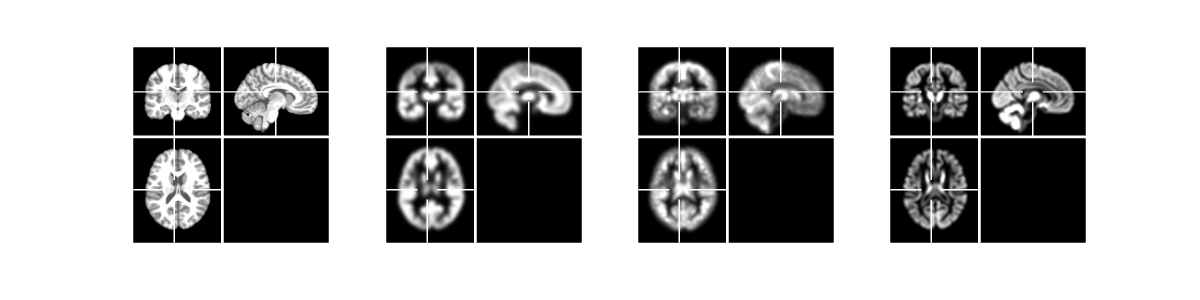


figure;
next; plot_mri({mni_frac,extension_mean_mni,extension_std_mni,junction_mean_mni},'off','enhance',@amp)
lay_fig([12,3])

## visualize CAT12 + MAP18 results

control_niidir = 'F:\Dataset\Brain\FCD_maps\data\control\';
patient_niidir = 'F:\Dataset\Brain\FCD_maps\data\patient\';
fcdmap_dir = 'F:\Dataset\Brain\FCD_maps\data\control\ZYS\p0\';
fcdmap_headstr = 'wm';
savemap_dir = '';

cur_niis = dir([control_niidir,'*.nii']);
for i_sub = 1:length(cur_niis)
    disp_wait(i_sub,length(cur_niis))

    sub_dir = control_niis(i_sub).name;
    sub_dir = sub_dir(1:9);
    subj_dir = [root_dir,sub_dir];
    % map_nii = MRI_read_Data([patient_niidir,patient_niis(i_sub).name],'verbose',0);
    
    map_nii = MRI_read_Data([fcdmap_dir,fcdmap_headstr,cur_niis(i_sub).name,'.gz'],'verbose',0);
    T_sub2mni = MRI_read_Data([subj_dir,'\T1_rb\sub2mni.map.nii.gz'],'verbose',0);
    T1reg_mri = MRI_warp(T_sub2mni,map_nii);

    T1reg_mri.data = mat_cut(3*T1reg_mri.data-1,0);

    temp = [root_dir,sub_dir,'/T1_rb/'];
    mkdir_silent(temp)
    MRI_save_File(T1reg_mri.data,[temp,'T1.norm_reg.nii.gz'],'info',mni_frac);
end

  E 00:06:10  94% [=====================================>..] R 00:01:53 Progress: 81/86 

file D:\File\work_file\Dataset\Brain\openFCD\sub-00171\T1_rb\sub2mni.map.nii.gz not exist!


错误使用 error
输入参数的数目不足。

出错 MRI_read_Data (第 14 行)
        error

### generate maps figure montage in roi location

fcdmap_headstrs = {'extension_map_','junction_map_'};
savefig_dir = 'F:\Dataset\Brain\openFCD\forDL\mtgFig\MAP18\';

i_list = 1:length(patient_niis);
% i_list = [9    12    23    38    61    64    71];

vol_mri = [];
error_idx = [];
fig = figure;
for i_sub = i_list
    try
        disp_wait(i_sub,length(patient_niis))

        sub_dir = patient_niis(i_sub).name;
        sub_dir = sub_dir(1:9);
        vol_mri{1} = MRI_read_Data([root_dir,sub_dir,'\T1_rb\T1.pvc.frac_reg.nii.gz'],'verbose',0);
        fcdmap_dir = [root_dir,sub_dir,'/save/MAP18/'];
        for j = 1:length(fcdmap_headstrs)
            vol_mri{j+1} = MRI_read_Data([fcdmap_dir,fcdmap_headstrs{j},sub_dir,'.nii.gz'],'verbose',0);
        end

        lab_mri = MRI_read_Data([root_dir,sub_dir,'\T1_rb\FLAIR_roi_reg.nii.gz'],'verbose',0);
        roi_cen = get_cen(lab_mri.data,plX,plY,plZ);
        lay_sub(2,2)
        next; plot_mri([vol_mri],'off',roi_cen,'enhance',@(x) amp(x,1e-4));
        lay_fig([8,8])

        saveas(fig,savefig_dir+"/"+sub_dir+".MAP18.mtg.png")

    catch e
        disp_error(e)
        error_idx(end+1) = i_sub;
    end
    clf(fig)
end

  E 00:01:18   1% [........................................] R 01:03:29 Progress: 1/84 

             type: {[2]  ''}
    hasBeenCaught: 1
       identifier: 'MATLAB:sizeDimensionsMustMatch'
          message: '对于此运算，数组的大小不兼容。'
     defaultstack: [2×1 struct]
    enhancedstack: [2×1 struct]
        arguments: {}

                                               file                                                                 name                       line
    __________________________________________________________________________________________    _________________________________________    ____

    {'C:\Users\admin\AppData\Local\Temp\Editor_wyqvu\LiveEditorEvaluationHelperE2052732855.m'}    {'get_cen'                              }    260 
    {'C:\Users\admin\AppData\Local\Temp\Editor_wyqvu\LiveEditorEvaluationHelperE2052732855.m'}    {'LiveEditorEvaluationHelperE2052732855'}     67 



### 模仿 generate_maps.m 、generate_reference.m 与 get_convolution.m

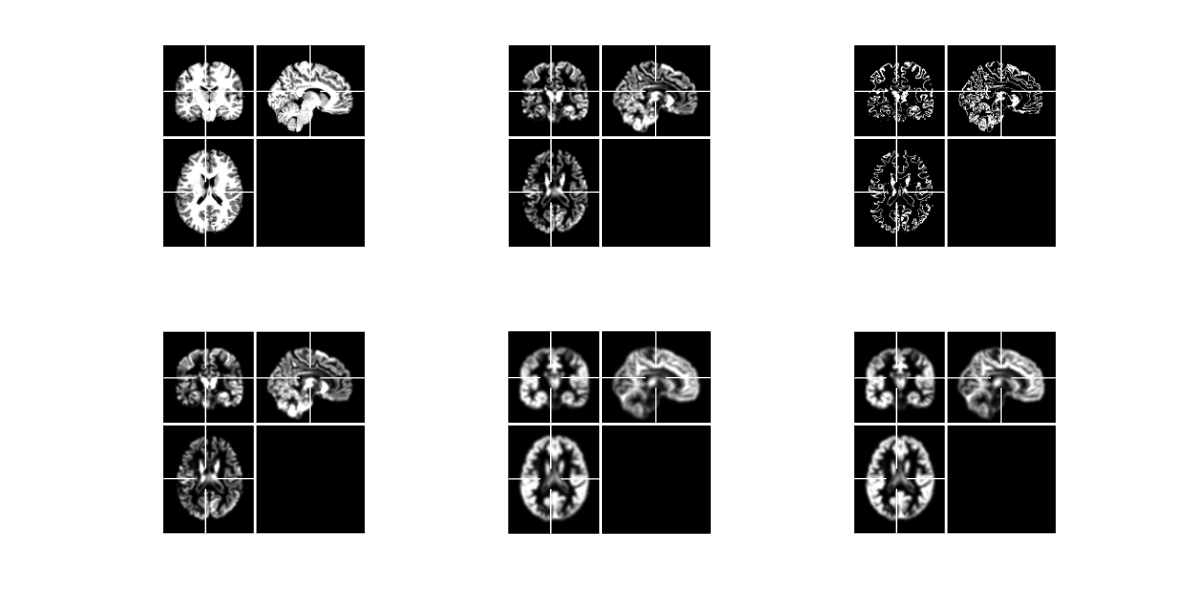

T1frac = MRI_read_Data('D:\File\work_file\Dataset\Brain\openFCD\sub-00003\T1_rb\T1.pvc.frac_reg.nii.gz','verbose',0);

imgBrain = T1frac.data;
imgGM = abs(imgBrain - 1) < 0.5;
imgWM = abs(imgBrain - 2) < 0.5;

% MAP18 def
kernel_conv = 5; %default: 5
kernel_smoothing = 6; %default: 6
std_factor = 0.5; %default: 0.5

% ZYS def
WGM_thresh = 0.3;
WGM_sm = 2;
GM_sm = 2.5;

addpath E:\work_Code\Matlab\from_github\fcd_maps-master
[convolved_img, binary_img] = get_convolution(imgBrain, imgGM, imgWM, std_factor, kernel_conv);
smoothed_img = get_smoothing(single(imgGM), kernel_smoothing);

imgWGM = abs(imgBrain - 1.5) < WGM_thresh;
imgWGM_sm = imgaussfilt3(single(imgWGM),WGM_sm);
imgGM_sm = imgaussfilt3(single(imgGM),GM_sm);

figure;
next; plot_mri({imgBrain,convolved_img, binary_img,imgWGM_sm,smoothed_img,imgGM_sm},'off','enhance',@amp)
lay_fig([12,6])

### 从T1frac连续组分中通过加权提取单个组分

#### 满足多组分概率和为1，且组分中心概率为1，离中心距离1则降为0

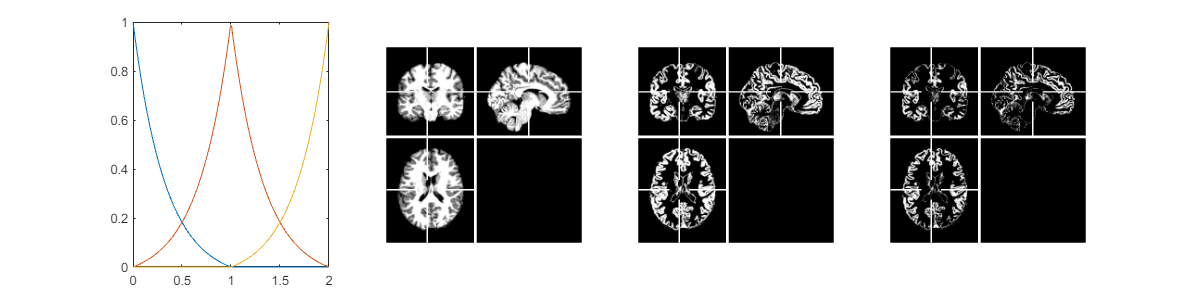

x = linspace(0,2,200);
w0 = weighting_sing(x,0);
w1 = weighting_sing(x,1);
w2 = weighting_sing(x,2);

imgGM = weighting_mult(imgBrain,1);
GM = 1 - 2*abs(imgBrain - 1); GM(GM<0) = 0;

figure;
next; plot(x,[w0;w1;w2]'); next; plot_mri({imgBrain,imgGM,GM},'off','enhance',@amp)
lay_fig([12,3])

control_niis = dir([patient_niidir,'*.nii']);

WGM_sumL1 = 0*imgBrain;
WGM_sumL2 = 0*imgBrain;
GM_sumL1 = 0*imgBrain;
GM_sumL2 = 0*imgBrain;

num_control = length(control_niis);
for i_sub = 1:num_control
    disp_wait(i_sub,num_control)

    sub_dir = control_niis(i_sub).name;
    sub_dir = sub_dir(1:9);
    subj_dir = [root_dir,sub_dir];

    T1frac = MRI_read_Data([subj_dir,'\T1_rb\T1.pvc.frac_reg.nii.gz'],'verbose',0);
    [imgWGM_sm,imgGM_sm] = gen_filtmaps_frac(T1frac.data,WGM_sm,GM_sm);

    WGM_sumL1 = WGM_sumL1 + imgWGM_sm;
    WGM_sumL2 = WGM_sumL2 + imgWGM_sm.^2;
    GM_sumL1 = GM_sumL1 + imgGM_sm;
    GM_sumL2 = GM_sumL2 + imgGM_sm.^2;
end

  E 00:00:46 100% [=======================================>] R 00:00:00 Progress: 84/84 


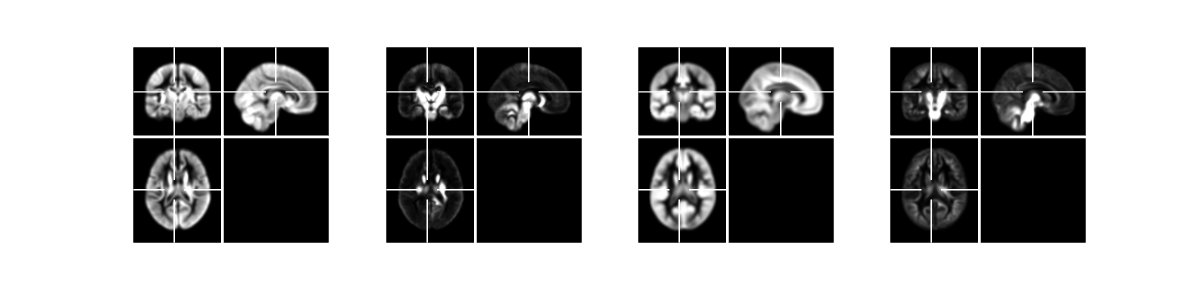

WGM_mean = WGM_sumL1/num_control;
WGM_std = WGM_sumL2/num_control - WGM_mean.^2;
GM_mean = GM_sumL1/num_control;
GM_std = GM_sumL2/num_control - GM_mean.^2;

saveREF_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\fcd_atlas\';
MRI_save_File(WGM_mean,[saveREF_dir,'WGM_mean_elastix.nii.gz']);
MRI_save_File(WGM_std,[saveREF_dir,'WGM_std_elastix.nii.gz']);
MRI_save_File(GM_mean,[saveREF_dir,'GM_mean_elastix.nii.gz']);
MRI_save_File(GM_std,[saveREF_dir,'GM_std_elastix.nii.gz']);

figure;
next; plot_mri({WGM_mean,WGM_std,GM_mean,GM_std},'off','enhance',@amp)
lay_fig([12,3])

## generate fcd reference with cat12-reged + zys filtering

controls_paths = get_files('*.nii','F:\Dataset\Brain\FCD_maps\data\control','fullname',1);
controls_paths = cellfun(@string,controls_paths);

patients_paths = get_files('*.nii','F:\Dataset\Brain\FCD_maps\data\patient','fullname',1);
patients_paths = cellfun(@string,patients_paths);

cat12_ref_file = 'E:\work_Code\Matlab\Toolbox\brain_science\Important\spm12\spm12\toolbox\cat12\templates_MNI152NLin2009cAsym\Template_0_GS.nii';
mask = [];
[~,h] = load_nifti(cat12_ref_file);
img_size = h.dim;
n_controls = size(controls_paths,1);

junction_mean_cat12_rsz = MRI_func_ROI(junction_mean_cat12,'imresize3',round(junction_mean_cat12.size*1.5));

wp0_dir = 'F:\Dataset\Brain\FCD_maps\data\control\ZYS\p0\';
WGM_sm = 2.5;
GM_sm = 4;

wp0_niis = dir([wp0_dir,'wy_*.nii.gz']);
for c = 1:n_controls
    disp_wait(c,n_controls)
    sub_nii = wp0_niis(c).name;
    sub_nii = sub_nii(4:end);

    % [img_brain, img_gm, img_wm, h] = load_brain_images(controls_paths(c), mask);
    T1frac = MRI_read_Data([wp0_dir,'wy_',sub_nii],'verbose',0);
    LAB = T1frac.data;
    LAB(isnan(LAB)) = 0;
    [imgWGM_sm,imgGM_sm] = gen_filtmaps_frac(LAB,WGM_sm,GM_sm);
    img_conv = imgWGM_sm; img_smooth = imgGM_sm;

    if c==1
        j_mean = zeros(size(img_conv));
        img_size = size(img_conv);
        smooths = zeros([n_controls img_size]);

        thick_L1sum = j_mean;
        thick_L2sum = j_mean;
    end
    %if c==1, e_map_controls = zeros(size(img_conv));  end

    j_mean = img_conv + j_mean;

    % img_smooth = get_smoothing(img_gm, kernel_smoothing);
    smooths(c,:,:,:) = img_smooth;

    % soft thickness
    T1thickness = MRI_read_Data([wp0_dir,'wy.sep.thickness_',sub_nii],'verbose',0);
    thick = single(T1thickness.data);
    thick_L1sum = thick + thick_L1sum;
    thick_L2sum = thick.^2 + thick_L2sum;
end

  E 00:00:55 100% [=======================================>] R 00:00:00 Progress: 78/78 


save_dir = 'F:\Dataset\Brain\FCD_maps\data\control\ZYS\reference\';
% MRI_save_File(j_mean,[save_dir,'j_mean.nii.gz'],'info',T1frac);
% MRI_save_File(e_mean,[save_dir,'e_mean.nii.gz'],'info',T1frac);
% MRI_save_File(e_std,[save_dir,'e_std.nii.gz'],'info',T1frac);

thick_std = thick_L2sum/n_controls - thick_mean.^2;
thick_std = mat_cut(thick_std).^0.5;
MRI_save_File(thick_std,[save_dir,'thick_std.nii.gz'],'info',T1frac);

wp0_dir = 'F:\Dataset\Brain\FCD_maps\data\control\ZYS\p0\';
WGM_sm = 2.5;
GM_sm = 4;

wp0_niis = dir([wp0_dir,'norm.reg_*.nii.gz']);
n_controls = length(wp0_niis);
for c = 1:n_controls
    disp_wait(c,n_controls)
    sub_nii = wp0_niis(c).name;
    sub_nii = sub_nii(10:end);

    T1frac = MRI_read_Data([wp0_dir,'norm.reg_',sub_nii],'verbose',0);
    LAB = mat_cut(3*T1frac.data-1,0);
    LAB(isnan(LAB)) = 0;

    [GM,WG] = get_GMWG(LAB);

    if c==1
        temp = 0*single(mni_gray.data);
        GM_L1sum = temp; WG_L1sum = temp;
        frac_L1sum = temp;

        GM_L2sum = temp; WG_L2sum = temp;
        frac_L2sum = temp; thick_L2sum = temp;

        % GMs = zeros([size(img_conv),n_controls]);
        % WGs = GMs; fracs = GMs; thicks = GMs;
    end
    % 
    % thick = single(T1thickness.data);
    GM_L1sum = GM + GM_L1sum;
    WG_L1sum = WG + WG_L1sum;
    frac_L1sum = LAB + frac_L1sum;
    % thick_L1sum = thick + thick_L1sum;

    GM_L2sum = GM.^2 + GM_L2sum;
    WG_L2sum = WG.^2 + WG_L2sum;
    frac_L2sum = LAB.^2 + frac_L2sum;
    % thick_L2sum = thick.^2 + thick_L2sum;

    % GMs(:,:,:,ii) = GM;
    % WGs(:,:,:,ii) = WG;
    % fracs(:,:,:,ii) = LAB;
    % thicks(:,:,:,ii) = thick;
end

  E 00:00:41 100% [=======================================>] R 00:00:00 Progress: 78/78 


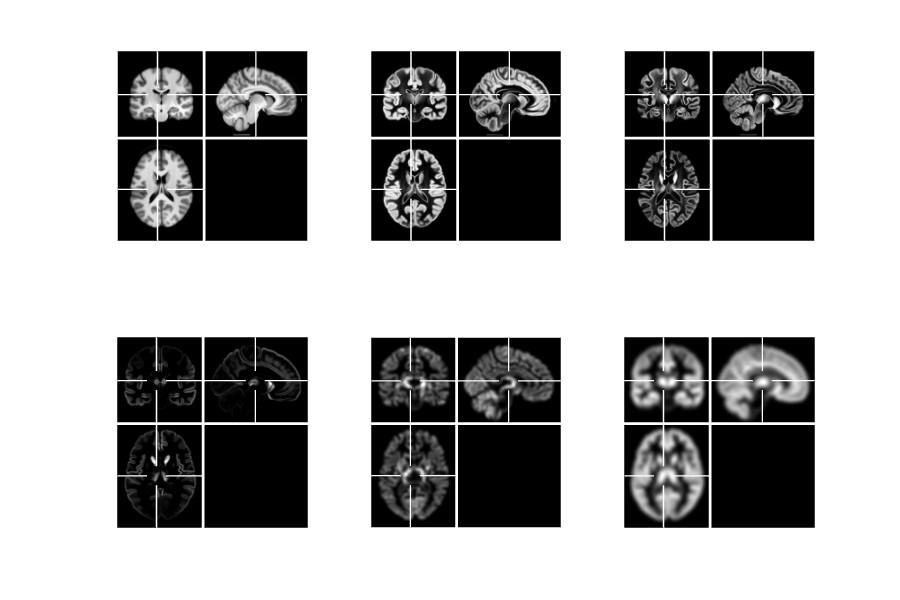

GM_mean = GM_L1sum/n_controls;
WG_mean = WG_L1sum/n_controls;
frac_mean = frac_L1sum/n_controls;
% thick_mean = thick_L1sum/n_controls;

save_dir = 'F:\Dataset\Brain\FCD_maps\data\control\ZYS\reference\';
% 
MRI_save_File(GM_mean,[save_dir,'T1.GM.mean.nii.gz'],'info',T1frac);
MRI_save_File(WG_mean,[save_dir,'T1.WG.mean.nii.gz'],'info',T1frac);
MRI_save_File(frac_mean,[save_dir,'T1.mean.nii.gz'],'info',T1frac);

figure;
next; plot_mri({frac_mean,GM_mean,WG_mean,thick_mean,j_mean,e_mean},'enhance',@(x) amp(x,1e-4))
lay_fig([9,6])

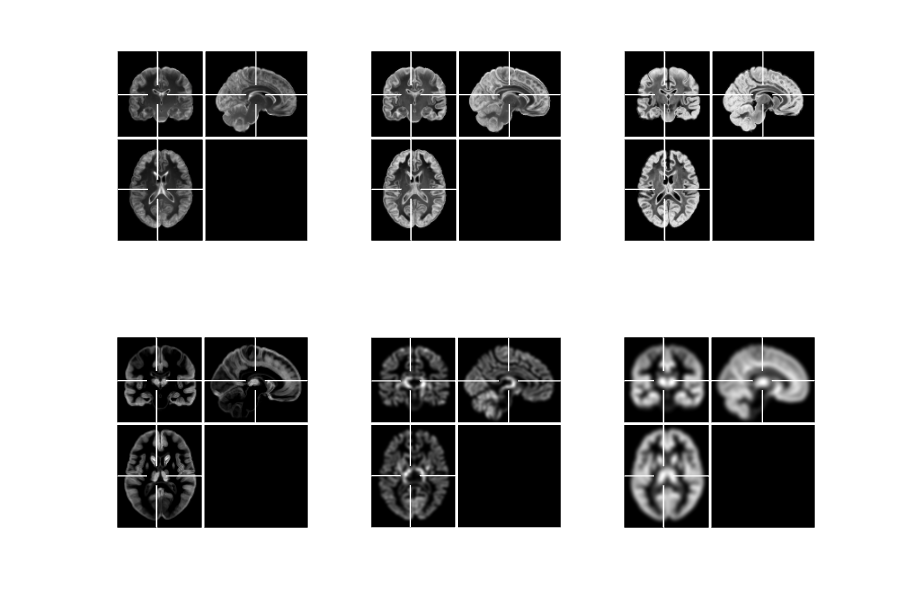

GM_std = GM_L2sum/n_controls - GM_mean.^2;
WG_std = WG_L2sum/n_controls - WG_mean.^2;
frac_std = frac_L2sum/n_controls - frac_mean.^2;
% thick_std = thick_L2sum/n_controls - thick_mean.^2;

mask = mni_gray.data>0;
GM_std = mat_cut(GM_std).^0.5 .* mask;
WG_std = mat_cut(WG_std).^0.5 .* mask;
frac_std = mat_cut(frac_std).^0.5 .* mask;
% thick_std = mat_cut(thick_std).^0.5;
 
% GM_std = std(GMs,[],4);
% WG_std = std(WGs,[],4);
% frac_std = std(fracs,[],4);
% thick_std = std(thicks,[],4);

clear GMs WGs fracs thicks

save_dir = 'F:\Dataset\Brain\FCD_maps\data\control\ZYS\reference\';

MRI_save_File(GM_std,[save_dir,'T1.GM.std.nii.gz'],'info',T1frac);
MRI_save_File(WG_std,[save_dir,'T1.WG.std.nii.gz'],'info',T1frac);
MRI_save_File(frac_std,[save_dir,'T1.std.nii.gz'],'info',T1frac);
% MRI_save_File(thick_std,[save_dir,'thick_std.nii.gz'],'info',T1frac);

figure;
next; plot_mri({frac_std,GM_std,WG_std,thick_std,j_mean,e_mean},'enhance',@(x) amp(x,1e-4))
lay_fig([9,6])

p0_dir = 'F:\Dataset\Brain\FCD_maps\data\patient\ZYS\p0\';
roi_dir = 'F:\Dataset\Brain\FCD_maps\data\patient\ZYS\ROI\';
savefig_dir = 'F:\Dataset\Brain\FCD_maps\data\patient\ZYS\mtg_zys\';
i_list = 1:length(patient_niis);
% i_list = [9    12    23    38    61    64    71];

sz = TEMP0_mrirsz.size;
[plX,plY,plZ] = meshgrid(1:sz(2),1:sz(1),1:sz(3));
vol_mri = [];
error_idx = [];
fig = figure;
for i_sub = i_list
    try
        disp_wait(i_sub,length(patient_niis))

        sub_nii = patient_niis(i_sub).name;
        sub_dir = sub_nii(1:9);
        T1frac = MRI_read_Data([p0_dir,'wy_',sub_nii,'.gz'],'verbose',0);
        T1thick = MRI_read_Data([p0_dir,'wy.sep.thickness_',sub_nii,'.gz'],'verbose',0);
        lab_mri = MRI_read_Data([roi_dir,'roi_',sub_nii,'.gz'],'verbose',0);
        roi_cen = get_cen(lab_mri.data,plX,plY,plZ);

        [imgWGM_sm,imgGM_sm] = gen_filtmaps_frac(T1frac.data,WGM_sm,GM_sm);
        [j_map,e_map] = get_fcdmap_zys(imgWGM_sm,imgGM_sm,j_mean,e_mean,e_std);
        thick_map = mat_cut(imgaussfilt3(single(T1thick.data) - thick_mean,3),0);

        lay_sub(2,2)
        next; plot_mri({T1frac,lab_mri,e_map,j_map},'off',roi_cen,'enhance',@(x) amp(x,1e-4));
        lay_fig([8,8])

        saveas(fig,savefig_dir+"/"+sub_dir+".MAP18.mtg.png")

    catch e
        disp_error(e)
        error_idx(end+1) = i_sub;
    end
    clf(fig)
end

  E 00:00:19  11% [===>....................................] R 00:02:32 Progress: 9/84 

    identifier: 'MATLAB:badsubscript'
       message: '位置 1 处的索引无效。数组索引必须为正整数或逻辑值。'

                                               file                                                                 name                       line
    __________________________________________________________________________________________    _________________________________________    ____

    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }    179 
    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }     17 
    {'C:\Users\admin\AppData\Local\Temp\Editor_wyqvu\LiveEditorEvaluationHelperE2052732855.m'}    {'LiveEditorEvaluationHelperE2052732855'}    255 



  E 00:00:24  14% [=====>..................................] R 00:02:26 Progress: 12/84 

    identifier: 'MATLAB:badsubscript'
       message: '位置 1 处的索引无效。数组索引必须为正整数或逻辑值。'

                                               file                                                                 name                       line
    __________________________________________________________________________________________    _________________________________________    ____

    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }    179 
    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }     17 
    {'C:\Users\admin\AppData\Local\Temp\Editor_wyqvu\LiveEditorEvaluationHelperE2052732855.m'}    {'LiveEditorEvaluationHelperE2052732855'}    255 



  E 00:00:47  27% [==========>.............................] R 00:02:03 Progress: 23/84 

    identifier: 'MATLAB:badsubscript'
       message: '位置 1 处的索引无效。数组索引必须为正整数或逻辑值。'

                                               file                                                                 name                       line
    __________________________________________________________________________________________    _________________________________________    ____

    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }    179 
    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }     17 
    {'C:\Users\admin\AppData\Local\Temp\Editor_wyqvu\LiveEditorEvaluationHelperE2052732855.m'}    {'LiveEditorEvaluationHelperE2052732855'}    255 



  E 00:01:15  45% [=================>......................] R 00:01:33 Progress: 38/84 

    identifier: 'MATLAB:badsubscript'
       message: '位置 1 处的索引无效。数组索引必须为正整数或逻辑值。'

                                               file                                                                 name                       line
    __________________________________________________________________________________________    _________________________________________    ____

    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }    179 
    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }     17 
    {'C:\Users\admin\AppData\Local\Temp\Editor_wyqvu\LiveEditorEvaluationHelperE2052732855.m'}    {'LiveEditorEvaluationHelperE2052732855'}    255 



  E 00:01:56  73% [============================>...........] R 00:00:47 Progress: 61/84 

    identifier: 'MATLAB:badsubscript'
       message: '位置 1 处的索引无效。数组索引必须为正整数或逻辑值。'

                                               file                                                                 name                       line
    __________________________________________________________________________________________    _________________________________________    ____

    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }    179 
    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }     17 
    {'C:\Users\admin\AppData\Local\Temp\Editor_wyqvu\LiveEditorEvaluationHelperE2052732855.m'}    {'LiveEditorEvaluationHelperE2052732855'}    255 



  E 00:02:01  76% [=============================>..........] R 00:00:41 Progress: 64/84 

    identifier: 'MATLAB:badsubscript'
       message: '位置 1 处的索引无效。数组索引必须为正整数或逻辑值。'

                                               file                                                                 name                       line
    __________________________________________________________________________________________    _________________________________________    ____

    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }    179 
    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }     17 
    {'C:\Users\admin\AppData\Local\Temp\Editor_wyqvu\LiveEditorEvaluationHelperE2052732855.m'}    {'LiveEditorEvaluationHelperE2052732855'}    255 



  E 00:02:15  85% [=================================>......] R 00:00:26 Progress: 71/84 

    identifier: 'MATLAB:badsubscript'
       message: '位置 1 处的索引无效。数组索引必须为正整数或逻辑值。'

                                               file                                                                 name                       line
    __________________________________________________________________________________________    _________________________________________    ____

    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }    179 
    {'E:\work_Code\Matlab\ZYS\Clinic\File_IO\plot_mri.m'                                     }    {'plot_mri'                             }     17 
    {'C:\Users\admin\AppData\Local\Temp\Editor_wyqvu\LiveEditorEvaluationHelperE2052732855.m'}    {'LiveEditorEvaluationHelperE2052732855'}    255 



  E 00:02:43 100% [=======================================>] R 00:00:01 Progress: 84/84 


# process in mni space, mean template

saveREF_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\fcd_atlas\';

% val_strs = {'j_mean','e_mean','e_std','GM_mean','WG_mean','frac_mean','thick_mean'};
val_strs = {'GM_std','WG_std','frac_std','thick_std'};
for i = 1:length(val_strs)
    val_str = val_strs{i};
    eval_str = [val_str,'_mni = func_repos_cat12_rsz(T1frac,mni_frac,',val_str,');'];
    eval(eval_str)
    eval_str = ['MRI_save_File(',val_str,'_mni,[saveREF_dir,''',val_str,'_cat12.nii.gz'']);'];
    eval(eval_str)
end

  1    1    1 => 13   13    7
170  206  170 =>182  217  175
  1    1    1 => 13   13    7
170  206  170 =>182  217  175
  1    1    1 => 13   13    7
170  206  170 =>182  217  175
  1    1    1 => 13   13    7
170  206  170 =>182  217  175


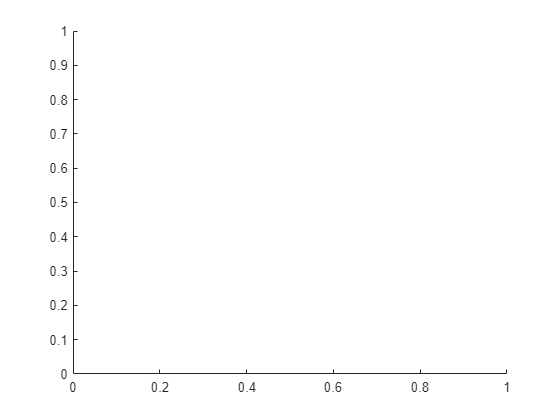

函数或变量 'j_mean_mni' 无法识别。



figure;
next; plot_mri({j_mean_mni,e_mean_mni,GM_mean_mni,WG_mean_mni,frac_mean_mni,thick_mean_mni},'enhance',@(x) amp(x,1e-4))

lay_fig([12,5])

saveREF_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\fcd_atlas\';
% feature_names = {'T1','T1.grad','T1.WG','T1.thickness','T2','T1.depth'};
% val_strs = {'j_mean','e_mean','e_std','GM_mean','WG_mean','frac_mean','thick_mean'};
val_strs = {'frac_mean','GM_mean','WG_mean','thick_mean'};

tic
map_tex3D = [];  map_Ren3D = [];
for j = 1:length(val_strs)
    val_str = val_strs{j};
    mri = MRI_read_Data([saveREF_dir,val_str,'_cat12.nii.gz']);

    [map_tex3D{j},map_Ren3D{j}] = Pilo_gen(mri,'XYZ',mni_XYZ8c,'Nxy',k*divN/2,'Nz',[],'tex_lim',{'1','99',1.5}, ...
        'alpha_list',[1,0.25],'proj_func',[],'proj_view','out');
    map_tex3D{j} = uint8(255*amp(map_tex3D{j}.data,0));
    map_Ren3D{j} = uint8(255*amp(map_Ren3D{j}.data,0));

    MRI_save_File(map_tex3D{j},[saveREF_dir,val_str,'_cat12.tex3D.nii.gz'])
    MRI_save_File(map_Ren3D{j},[saveREF_dir,val_str,'_cat12.ren3D.nii.gz'])
end

sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]


toc

历时 13.471556 秒。


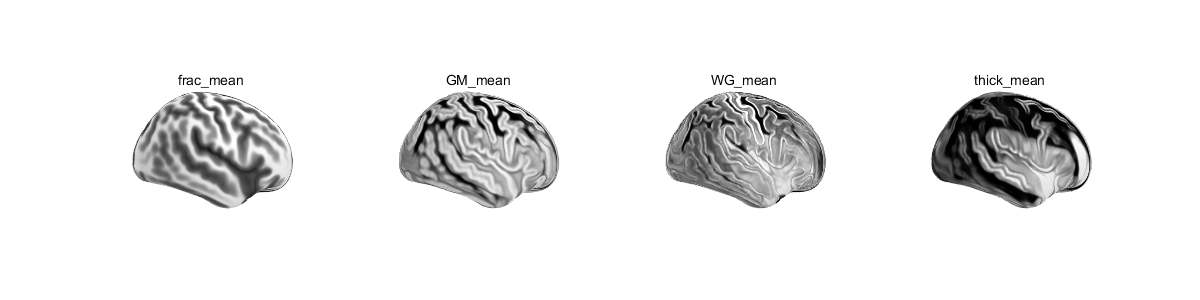

mni_XYZbin = zeros(Nxy/2,Nxy/2,Nz,3);
for i = 1:Nz
    temp = imresize_grid(mni_XYZ8c.data(:,:,i,:),[Nxy,Nxy]/2);
    mni_XYZbin(:,:,i,:) = permute(temp,[1,2,4,3]);
end

mni_depthbin = mni_depth3D.data(1:2:end,1:2:end,:);
ax = [];
figure; lay_sub(1,4)
for j = 1:length(val_strs)
    ax{j} = next;
    plot_pilos(mni_XYZbin,amp(map_Ren3D{j},0.04),[],'depth3D',mni_depthbin*10,'parent',ax{j});
    ax{j}.UserData.depth_change_fcn(30)
    view(90,0); axis off; legend off; title(val_strs{j})
    pause(1)
end
lay_fig([12,3]);
sld = findobj('Tag','z_slider'); delete(sld)
for j = 1:length(val_strs)
    axes(ax{j}); camzoom(1.5);
    ax{j}.CameraViewAngle = ax{1}.CameraViewAngle;
end
lay_linkview

% J_mean = WGM_mean;
% E_mean = GM_mean; E_std = GM_std;

J_mean = j_mean_mni.data; E_mean = e_mean_mni.data; E_std = e_std_mni.data;

sub_dir = 'sub-00003';
% T1frac = MRI_read_Data([root_dir,sub_dir,'\T1_rb\T1.pvc.frac_reg.nii.gz'],'verbose',0);
% lab_mri = MRI_read_Data([root_dir,sub_dir,'\T1_rb\FLAIR_roi_reg.nii.gz'],'verbose',0);

T1frac = MRI_read_Data('F:\Dataset\Brain\FCD_maps\data\patient\ZYS\p0\wy_sub-00003_acq-iso08_T1w.nii.gz');

sMRI [206,170,170] res:[1,1,1]


T1frac = func_repos_cat12_rsz(T1frac,mni_frac,T1frac.data);

  1    1    1 => 13   13    7
170  206  170 =>181  218  175



roi_cen = get_cen(lab_mri.data,plX,plY,plZ);
roi_cen = [150,95,120];

[imgWGM_sm,imgGM_sm] = gen_filtmaps_frac(T1frac.data,WGM_sm,GM_sm);
[j_map,e_map] = get_fcdmap_zys(imgWGM_sm,imgGM_sm,J_mean,E_mean,E_std);
[GM,WG] = get_GMWG(T1frac.data);
WG = imgaussfilt3(WG,1);

[ssim_core,qualityMaps] = multissim3(WG,WG_mean_mni.data);
ssim_core

ssim_core = single
      0.96556


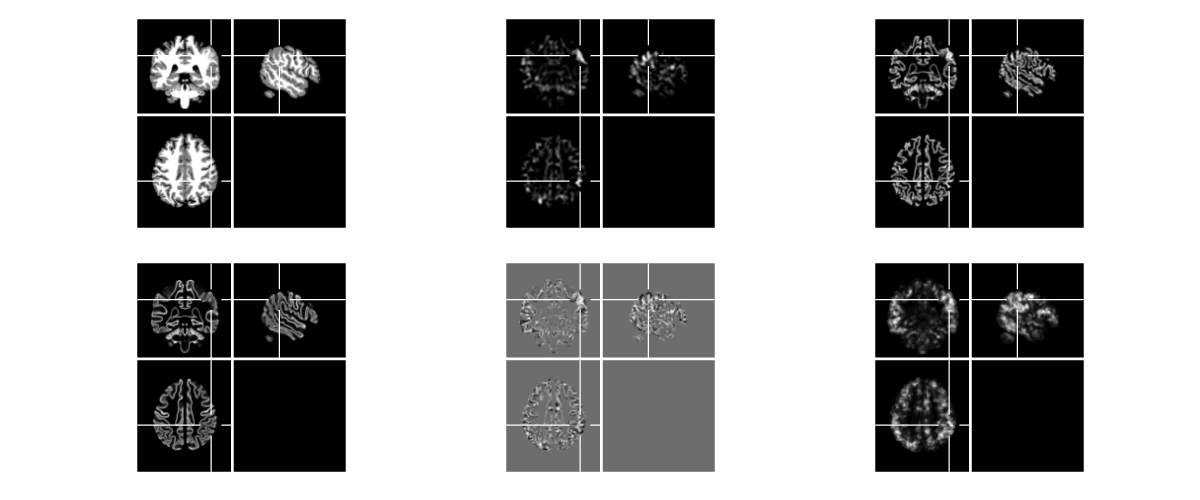


figure; lay_sub(2,3)
next; plot_mri({T1frac,j_map,WG,WG_mean_mni,WG-WG_mean_mni.data,1-qualityMaps{1}},'off',roi_cen,'enhance',@(x) amp(x,1e-4))
lay_fig([12,5])

function w = weighting_sing(x,a)
w_factor = 3; % 越大，加权中心越尖
f = @(x) exp(-w_factor*abs(x-a));
w = (f(x)-f(a+1))/(1-f(a+1));
w(w<0) = 0;
end

function w = weighting_mult(x,a)
w = weighting_sing(x,a);
wsum = weighting_sing(x,0) + weighting_sing(x,1)+ weighting_sing(x,2);
w = w./wsum;
end

function smoothed_img = get_smoothing(img, kernel)
%Smoothing calculated using the function provided in the SPM library
    smoothed_img = zeros(size(img));
    spm_smooth(img,smoothed_img,[kernel kernel kernel]);
end

function roi_cen = get_cen(roi,plX,plY,plZ)
roi(isnan(roi)) = 0;
roi_cenX = round(mean(single(roi).*plX,'all')./mean(roi,'all'));
roi_cenY = round(mean(single(roi).*plY,'all')./mean(roi,'all'));
roi_cenZ = round(mean(single(roi).*plZ,'all')./mean(roi,'all'));
roi_cen = [roi_cenX,roi_cenY,roi_cenZ];
end

function x = func_repos_cat12(x,ref)
% x.data = fliplr(x.data);
x = MRI_func_ROI(x,'repos',ref);
end

function x = func_repos_cat12_rsz(x,ref,data)
x.data = data;
x = MRI_func_ROI(x,'repos',ref);
end

function [imgWGM_sm,imgGM_sm] = gen_filtmaps_frac(imgBrain,WGM_sm,GM_sm)
WGM_thresh = 0.3;
imgWGM = abs(imgBrain - 1.5) < WGM_thresh;
imgWGM_sm = imgaussfilt3(single(imgWGM),WGM_sm);

imgGM = weighting_mult(imgBrain,1);
imgGM_sm = imgaussfilt3(single(imgGM),GM_sm);
end

function [imgWGM_sm,imgGM_sm] = gen_filtmaps_gmwm(imgGM,imgWM,WGM_sm,GM_sm)
WGM_thresh = 0.3;
imgWGM = (imgGM < WGM_thresh) & (imgWM < WGM_thresh);
imgWGM_sm = imgaussfilt3(single(imgWGM),WGM_sm);

imgGM_sm = imgaussfilt3(single(imgGM),GM_sm);
end

function [j_map,e_map] = get_fcdmap_zys(imgWGM_sm,imgGM_sm,j_mean,e_mean,e_std)
%JMAP generation
j_map = imgWGM_sm - j_mean;
j_map(j_map<0) = 0;

%EMAP generation
% img_smooth = get_smoothing(img_gm,kernel_smoothing);
e_diff = imgGM_sm - e_mean;
e_map = e_diff;
e_map(e_diff < e_std) = 0;
e_map = e_map.^2;
end

function [GM,WG] = get_GMWG(LAB)
GM = 1 - 1*abs(LAB - 1);
GM(GM<0) = 0;
WG = 1 - 2*abs(LAB-1.5);
WG(WG<0) = 0;
% WG = WG.*0.5;
end